# **1. Read the image**

**Read the image and resize to 1024  x 1024**

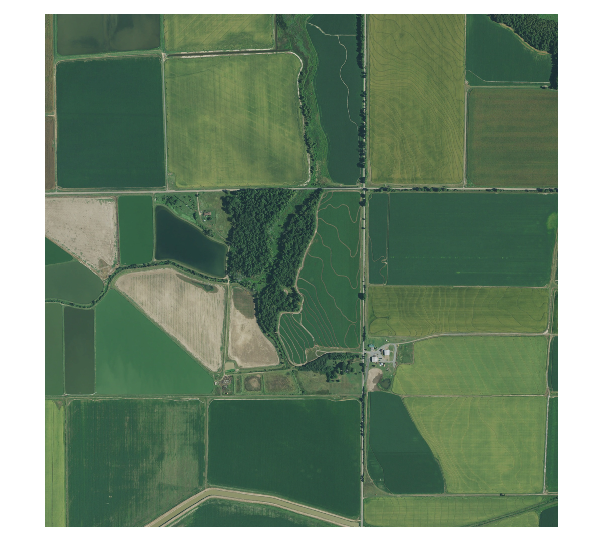

im = imread('field.jpg');
im = imresize(im, 0.50);
imshow(im);

**Convert to Gray Scale Image**

Grayim2 = rgb2gray(im)

Grayim2 = 1024×1024 uint8 matrix
   106   104   102   103   106   100    95   102   105   110   115   111   108    99   119   104    91    90    84    95   105    96    95    87    79    85    86    86    86    87    87    87    89    89    90    91    91    91    91    91    91    91    91    91    91    91    91    91    91    90
   105   102   102   106   100    95    96    98   109   110   114   112   109   101   117   103    93    92    84    94   104    93    92    88    78    84    85    86    87    87    88    88    89    89    90    91    91    91    91    91    91    91    91    91    91    91    91    91    91    90
   104   102   101   103   101   101    95   101   111   113   112   113   113   103   112   107    95    91    85    93   104    92    90    89    78    84    85    86    87    88    88    89    89    89    90    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91
   101   104   102    98   102   103    93   102   109   112   1

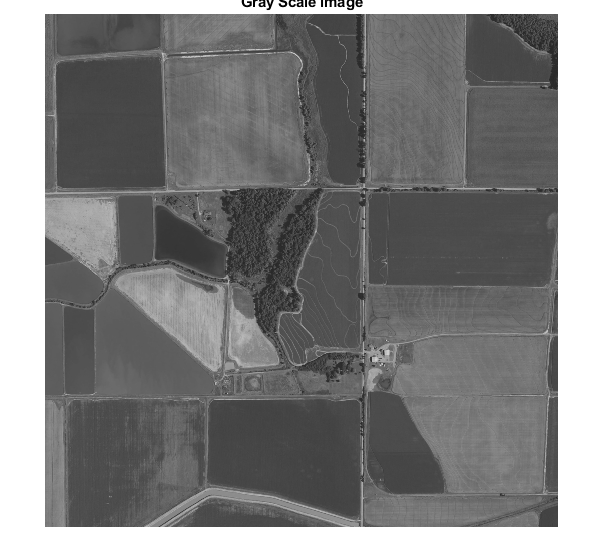

imshow(Grayim2), title("Gray Scale image");

# **2. Contrast Enhancement**

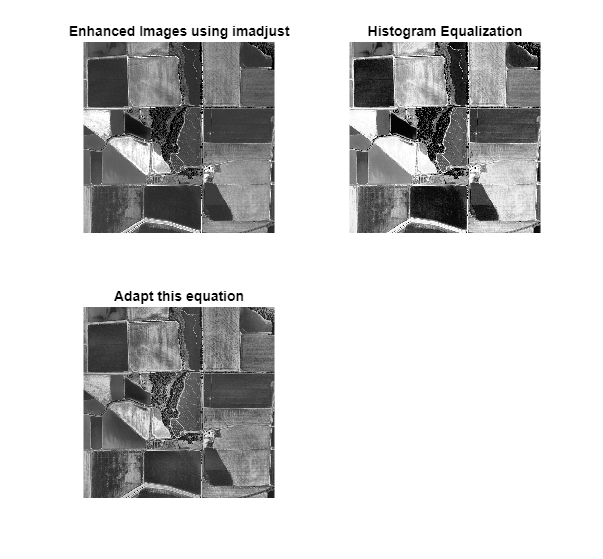

img_imadjust = imadjust(Grayim2);
img_histeq = histeq(Grayim2);
img_adapthisteq = adapthisteq(Grayim2);
figure(1);
subplot(2,2,1); imshow(img_imadjust); title("Enhanced Images using imadjust");
subplot(2,2,2); imshow(img_histeq); title("Histogram Equalization");
subplot(2,2,3); imshow(img_adapthisteq); title("Adapt this equation");

Find the best pics and run the filters on it.

# **3. Run the filters**

#### **3.1 GrayScale image**

- **Apply the sobel filter**

img_before = Grayim2

img_before = 1024×1024 uint8 matrix
   106   104   102   103   106   100    95   102   105   110   115   111   108    99   119   104    91    90    84    95   105    96    95    87    79    85    86    86    86    87    87    87    89    89    90    91    91    91    91    91    91    91    91    91    91    91    91    91    91    90
   105   102   102   106   100    95    96    98   109   110   114   112   109   101   117   103    93    92    84    94   104    93    92    88    78    84    85    86    87    87    88    88    89    89    90    91    91    91    91    91    91    91    91    91    91    91    91    91    91    90
   104   102   101   103   101   101    95   101   111   113   112   113   113   103   112   107    95    91    85    93   104    92    90    89    78    84    85    86    87    88    88    89    89    89    90    91    91    91    91    91    91    91    91    91    91    91    91    91    91    91
   101   104   102    98   102   103    93   102   109   112 

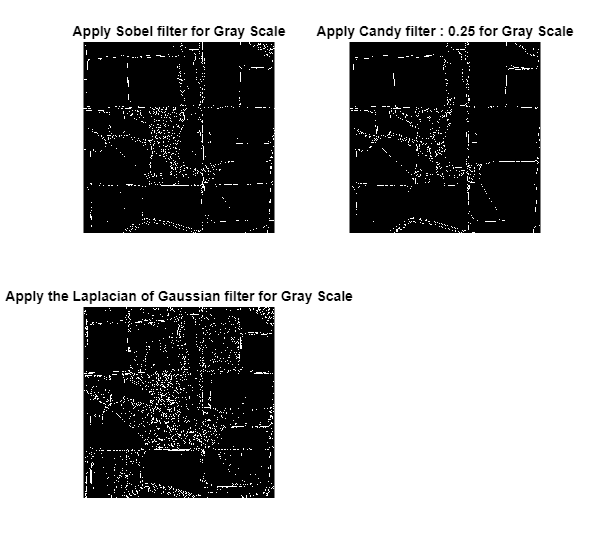

figure(1);
Sobel_Image1 = edge(img_before, 'sobel');
subplot(2,2,1,'align'); imshow(Sobel_Image1), title("Apply Sobel filter for Gray Scale");
Canny_image1 = edge(img_before, 'canny', 0.25);
subplot(2,2,2,'align');imshow(Canny_image1), title("Apply Candy filter : 0.25 for Gray Scale");
log_image1 = edge(img_before, 'log');
subplot(2,2,3,'align');imshow(log_image1), title("Apply the Laplacian of Gaussian filter for Gray Scale");

#### **3.2 Img_imadjust image**

- **Apply the sobel filter**

img_before = img_imadjust

img_before = 1024×1024 uint8 matrix
   124   120   116   118   124   112   101   116   122   133   143   135   129   110   152   120    93    91    78   101   122   103   101    84    67    80    82    82    82    84    84    84    89    89    91    93    93    93    93    93    93    93    93    93    93    93    93    93    93    91
   122   116   116   124   112   101   103   107   131   133   141   137   131   114   148   118    97    95    78    99   120    97    95    86    65    78    80    82    84    84    86    86    89    89    91    93    93    93    93    93    93    93    93    93    93    93    93    93    93    91
   120   116   114   118   114   114   101   114   135   139   137   139   139   118   137   126   101    93    80    97   120    95    91    89    65    78    80    82    84    86    86    89    89    89    91    93    93    93    93    93    93    93    93    93    93    93    93    93    93    93
   114   120   116   107   116   118    97   116   131   137 

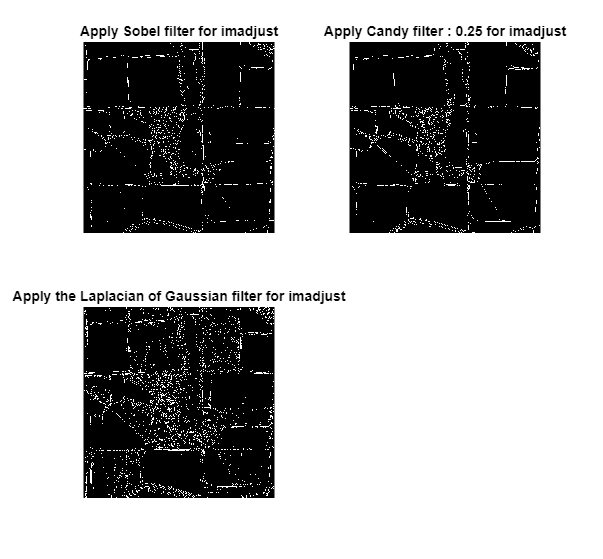

figure(1);
subplot(2,2,1); Sobel_Image2 = edge(img_before, 'sobel');
imshow(Sobel_Image2), title("Apply Sobel filter for imadjust");
subplot(2,2,2); Canny_image2 = edge(img_before, 'canny', 0.25);
imshow(Canny_image2), title("Apply Candy filter : 0.25 for imadjust");
subplot(2,2,3); log_image2 = edge(img_before, 'log');
imshow(log_image2), title("Apply the Laplacian of Gaussian filter for imadjust");

#### **3.3 Img_Histeq image**

img_before = img_histeq

img_before = 1024×1024 uint8 matrix
   170   162   158   158   170   150   138   158   166   182   198   186   174   146   210   162   121   117   105   138   166   138   138   109    85   105   109   109   109   109   109   109   117   117   117   121   121   121   121   121   121   121   121   121   121   121   121   121   121   117
   166   158   158   170   150   138   138   146   178   182   194   190   178   154   206   158   130   125   105   134   162   130   125   113    81   105   105   109   109   109   113   113   117   117   117   121   121   121   121   121   121   121   121   121   121   121   121   121   121   117
   162   158   154   158   154   154   138   154   186   190   190   190   190   158   190   174   138   121   105   130   162   125   117   117    81   105   105   109   109   113   113   117   117   117   117   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121
   154   162   158   146   158   158   130   158   178   190 

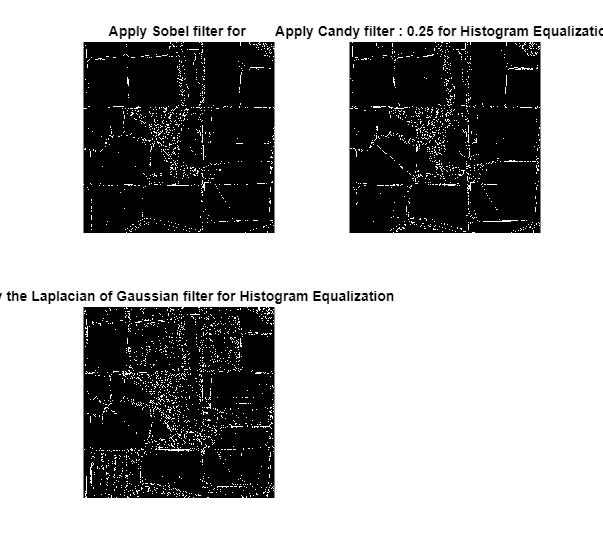

figure(1);
subplot(2,2,1); Sobel_Image3 = edge(img_before, 'sobel');
imshow(Sobel_Image3), title("Apply Sobel filter for ");
subplot(2,2,2); Canny_image3 = edge(img_before, 'canny', 0.25);
imshow(Canny_image3), title("Apply Candy filter : 0.25 for Histogram Equalization");
subplot(2,2,3); log_image3 = edge(img_before, 'log');
imshow(log_image3), title("Apply the Laplacian of Gaussian filter for Histogram Equalization");

#### **3.4 Adapthisteq image**

img_before = img_adapthisteq

img_before = 1024×1024 uint8 matrix
   163   156   149   152   163   142   128   149   159   172   181   174   168   139   186   156   119   116    94   128   159   130   128   105    77    98   101   101   101   105   105   105   112   112   116   119   119   119   119   119   119   119   119   119   119   119   119   119   119   116
   159   149   149   163   142   128   130   136   170   172   180   176   170   146   184   152   124   121    94   126   156   124   121   108    73    94    98   101   105   105   108   108   112   112   116   119   119   119   119   119   119   119   119   119   119   119   119   119   119   116
   156   149   146   152   146   146   128   146   174   178   176   178   178   152   176   165   128   119    98   124   156   121   116   112    73    94    98   101   105   108   108   112   112   112   116   119   119   119   119   119   119   119   119   119   119   119   119   119   119   119
   146   156   149   136   149   152   124   149   170   176 

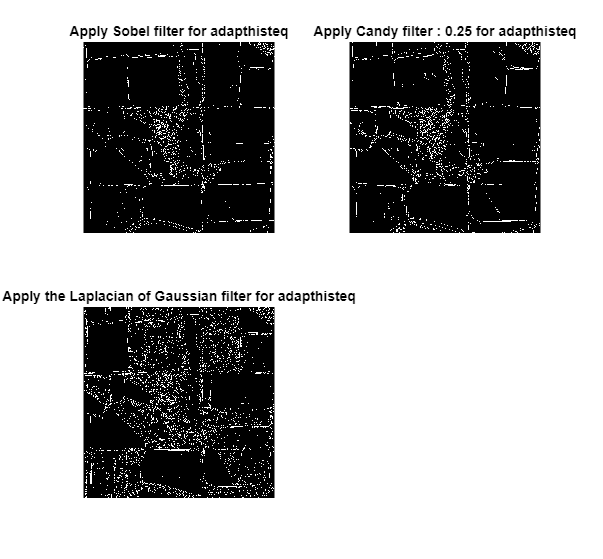

figure(1);
Sobel_Image4 = edge(img_before, 'sobel');
subplot(2,2,1); imshow(Sobel_Image4), title("Apply Sobel filter for adapthisteq");
Canny_image4 = edge(img_before, 'canny', 0.25);
subplot(2,2,2); imshow(Canny_image4), title("Apply Candy filter : 0.25 for adapthisteq");
log_image4 = edge(img_before, 'log');
subplot(2,2,3); imshow(log_image4), title("Apply the Laplacian of Gaussian filter for adapthisteq");

# **5. Remove the Noise**

Using morphology functions, remove pixels which do not belong to the objects of interest.

Remove all object containing fewer than 30 pixels.

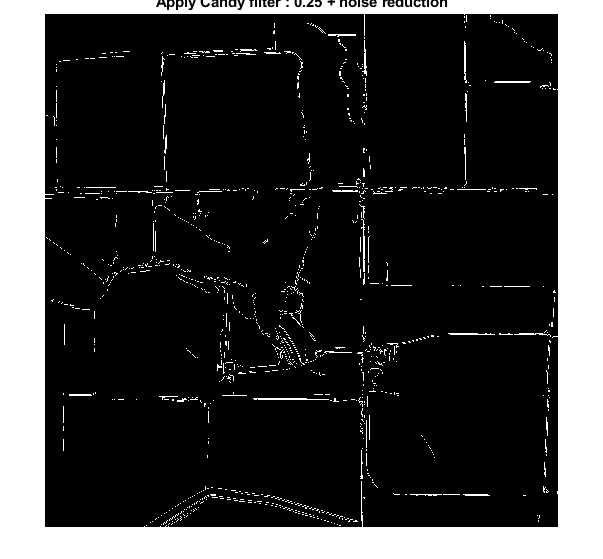

bw = bwareaopen(Sobel_Image1,30);
figure;
imshow(bw);title("Apply Candy filter : 0.25 + noise reduction");

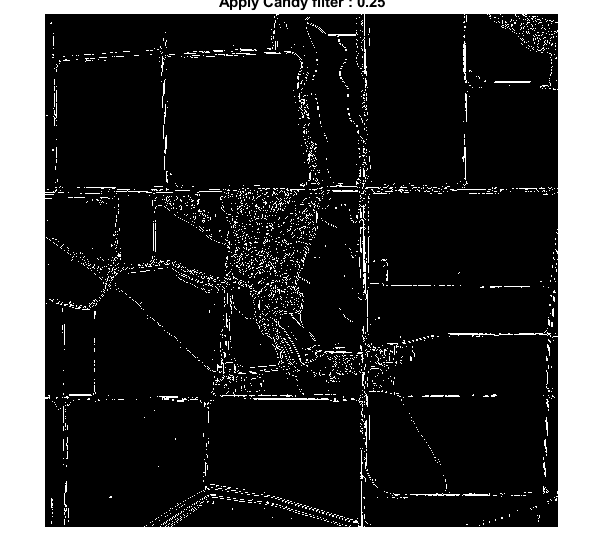

figure;
imshow(Sobel_Image1);title("Apply Candy filter : 0.25");

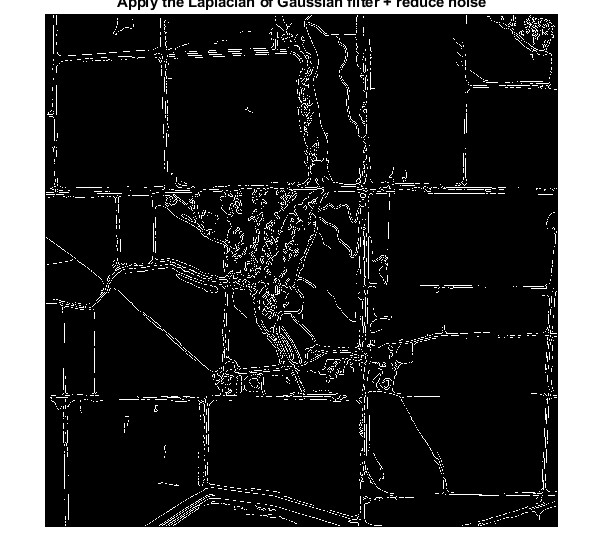

bw1 = bwareaopen(Canny_image3,30);
figure;
imshow(bw1); title("Apply the Laplacian of Gaussian filter + reduce noise");

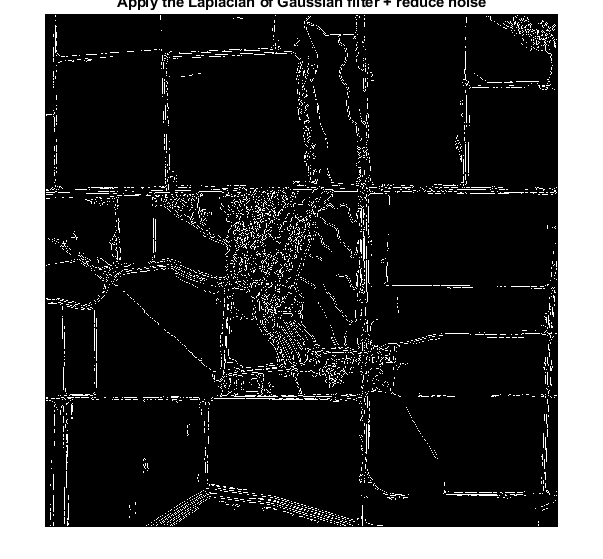

bw2 = bwareaopen(log_image1,30);
imshow(bw2); title("Apply the Laplacian of Gaussian filter + reduce noise");

# **6. Apply the transformer**

**HOUGH transform **

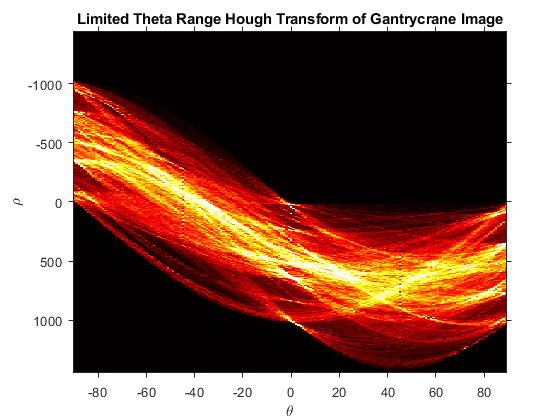

[H,T,R] = hough(bw1);
figure
imshow(imadjust(rescale(H)),'XData',T,'YData',R,...
   'InitialMagnification','fit');
title('Limited Theta Range Hough Transform of Gantrycrane Image');
xlabel('\theta')
ylabel('\rho');
axis on, axis normal;
colormap(gca,hot)

NumofLines = 15

NumofLines = 15

P  = houghpeaks(H,NumofLines,'threshold',ceil(0.5*max(H(:))));
x = T(P(:,2)); y = R(P(:,1));
%plot(x,y,'s','color','white');

visualize the detected lines

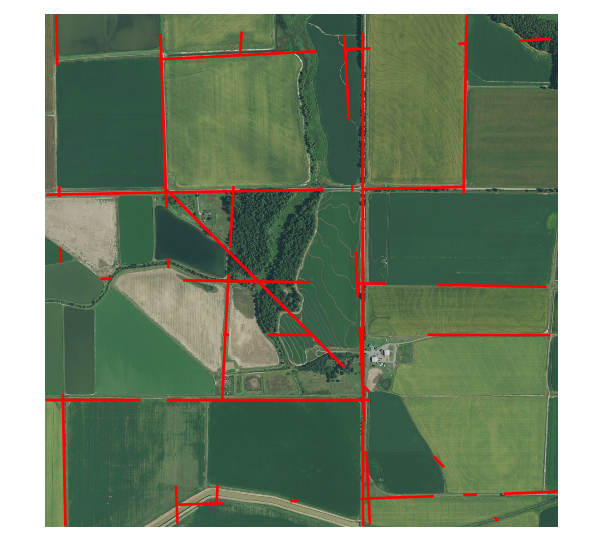


lines = houghlines(bw1,T,R,P,'FillGap',50,'MinLength',10);
figure, imshow(im), hold on
max_len = 0;
for k = 1:length(lines)
 xy = [lines(k).point1; lines(k).point2];
 plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','red');
    len = norm(lines(k).point1 - lines(k).point2);
   if ( len > max_len)
      max_len = len;
      xy_long = xy;
   end
end